# **Άσκηση 4**

Σκοπός της συγκεκριμένης άσκησης είναι η αποθορυβοποίηση ενός ηχητικού σήματος με αφαίρεση των φασματικών συνιστωσών του θορύβου. Η λογική στην οποία βασίζεται η συγκεκριμένη τεχνική είναι ότι ο θόρυβος λειτουργεί προσθετικά στο πεδίο του χρόνου και επομένως αντίστοιχα και στο πεδίο της συχνότητας.Έτσι, γνωρίζοντας ή κάνοντας μια εκτίμηση των συχνοτικών συνιστωσών του θορύβου μπορούμε να επιτύχουμε την αποθορυβοποίηση του σήματος.

Στη παρούσα άσκηση δοκιμάζονται τρεις επιπλέον τεχνικές για την αποθορυβοποίηση του σήματος από εκείνη της προηγούμενης άσκησης.

Αρχικά, εισάγουμε το αρχείο ήχου:

clear;
clc;
[x_init,Fs] = audioread("guit1.wav");

Προσθέτουμε λευκό Γκαουσιανό θόρυβο:

% Add noise
x = x_init + 0.01*randn(size(x_init));

% Uncomment to listen initial noisy signal
%soundsc(x,16000);

Έπειτα, χωρίζουμε το θορυβώδες σήμα σε frames:

X = frame_wind(x,256,0.5);
dim_X = size(X);

Υπολογίζουμε τον FFT κάθε frame και βρίσκουμε το μέτρο και τη γωνία του:

% Find FFT matrix of X
fft_mat = fft(X);
dim_fft = size(fft_mat);

% Find Measure and phase
measure = abs(fft_mat);
phase = angle(fft_mat);

Υπολογίζουμε την ενέργεια κάθε frame και βρίσκουμε τη μέγιστη ενέργεια:

% Find the energy of each frame
abs_fft_mat = abs(fft_mat);
squared_abs_fft_mat = abs_fft_mat.^2;
dim = size(squared_abs_fft_mat);
E = sum(squared_abs_fft_mat);
dim_E = size(E);

% Find Max Energy 
max_energy = max(E);

Επιλέγουμε την τεχνική που θέλουμε για να κάνουμε την εκτίμηση του θορύβου Ν(f) και καλούμε την συνάρτηση determine_noise για να μας επιστρέψει την εκτίμηση του θορύβου:

% Run for all values of technique(technique=2,3,4)
technique = 3;
noise = determine_noise(technique,X,measure,E,max_energy);

Στη συνέχεια, αφαιρούμε το θόρυβο από το μέτρο κάθε frame:

measure = denoise(technique,X,measure,E,max_energy,noise);

Στο επόμενο βήμα, ανασυνθέτουμε τον FFT του αποθορυβοποιημένου σήματος με χρήση του πλάτους και της φάσης, όπως φαίνεται στην ακόλουθη εξίσωση:

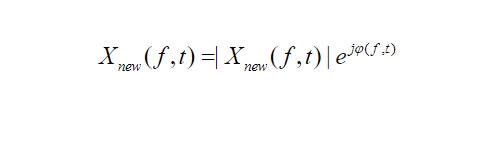

img = imread('FFT_Reconstruct_Equation.png');
imshow(img)

% Reconstruct FFT from measure and phase
X_new = measure .* exp(1j*phase);

Επιστρέφουμε στο πεδίο του χρόνου με χρήση του IFFT:

X_new_in_time = ifft(X_new);
X_new_in_time = real(X_new_in_time);

Aνακατασκευάζουμε το σήμα και ακούμε το τελικό αποτελέσμα:

y = frame_recon(X_new_in_time,0.5);
% Uncomment to listen to audio result
% soundsc(y,16000);

Αποθηκεύουμε το αποτέλεσμα σε ένα αρχείο με όνομα ανάλογα με την τεχνικη που χρησιμοποιήθηκε:

% Uncomment if you want to save again
% if technique == 2
%     audiowrite('Result_2.wav',y,16000);
% elseif technique == 3
%     audiowrite('Result_3.wav',y,16000);
% elseif technique == 4
%     audiowrite('Result_4.wav',y,16000);
% else
%     disp('Wrong initilization of technique!')
% end

Βρίσκουμε και το λόγο σήματος προς θόρυβο:

% Find SNR
y = y(1:140278).';
SNR = 10 * log10( sum(x_init.^2) ./ sum((x_init-y).^2) );

### **Υπορουτίνες determine_noise & denoise**

Υλοποιήθηκαν δύο υπορουτίνες/συναρτήσεις για την εφαρμογή των διαφορετικών τεχνικών της εργασίας. Η συνάρτηση determine_noise καθορίζει το προφίλ θορύβου ανάλογα με την τεχνική που θέλουμε να χρησιμοποιήσουμε. Παίρνει ως όρισμα τον αριθμό της τεχνικής που θέλουμε να εφαρμόσουμε καθώς και άλλες υπολογισμένες παραμέτρους του βασικού script(αναφέρονται αναλυτικά στο αρχείο της συνάρτησης) και επιστρέφει το θόρυβο που στοχεύουμε να εξάγουμε στο επόμενο στάδιο. Προχωρώντας στο επόμενο στάδιο εξάγουμε το θόρυβο με χρήση της υπορουτίνας denoise.Στην περίπτωση των τεχνικών 2 και 3 η συνάρτηση πραγματοποιεί μια απλή αφαίρεση του input noise από το μέτρο του. Στην τέταρτη τεχνική έχουμε επιλέξει η συνάρτηση determine_noise να δίνει ως έξοδο την έξοδο που θα έδινε και στην τεχνική 2, έτσι ώστε στη συνέχεια η συνάρτηση denoise να έχει αυτό ως αρχικό θόρυβο και να τον ανανεώνει σε περίπτωση που βρει frames με ενέργεια μικρότερη του 1% της μέγιστης. Ως έξοδο της τελευταίας συνάρτησης παίρνουμε το μέτρο του αποθορυβοποιημένου σήματος και έτσι είμαστε έτοιμοι να προχωρήσουμε στο βήμα της ανακατασκευής του αποθορυβοποιημένου σήματος.

### **Σύγκριση Αποτελεσμάτων**

Αν θέλαμε να κάνουμε τη γραφική παράσταση των ηχητικών αποτελεσμάτων, όπως φαίνεται πιο κάτω, δε θα μπορούσαμε να εξάγουμε κάποιο συμπέρασμα καθώς οι κυματομορφές φαίνονται αρκετά όμοιες.

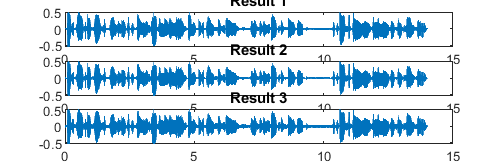

[x2,Fs] = audioread("Result_2.wav");
[x3,Fs] = audioread("Result_3.wav");
[x4,Fs] = audioread("Result_4.wav");

% Create Plots
subplot(3,1,1)
plot(x2);
title("Result 1")
subplot(3,1,2)
plot(x3);
title("Result 2")
subplot(3,1,3)
plot(x4);
title("Result 3")

Έτσι, στη συνέχεια ακούμε τους ήχους για να τους συγκρίνουμε και ηχητικά:

% Uncomment to listen audio result for specific technique
%soundsc(x2,16000);
%soundsc(x3,16000);
%soundsc(x4,16000);

### **Συμπεράσματα**

Προσπαθώντας να πραγματοποιήσουμε μια όσο το δυνατόν πιο αντικειμενική σύγκριση των παραπάνω τεχνικών μπορούμε να συγκρίνουμε τα SNR. Συγκρίνοντας τα SNR, λοιπόν,παρατηρούμε ότι η τρίτη τεχνική έχει μεγαλύτερο SNR και για αυτό θα μπορούσαμε να πούμε ότι είναι καλύτερη στην αποθορυβοποίηση. 

Η πρώτη τεχνική, όπως αναφέρθηκε στην άσκηση 3, αφαιρεί τον θόρυβο στο υπόβαθρο αλλά δημιουργεί την αίσθηση των απότομων διακοπών του ήχου. Η δεύτερη τεχνική δεν αφαιρεί στον ίδιο βαθμό με την πρώτη τον θόρυβο στο υπόβαθρο, άλλα δεν παρουσιάζει τόσες απότομες αλλαγές. Η τρίτη τεχνική ακούγεται ότι αποθορυβοποιεί καλύτερα το αρχικό ηχητικό σήμα συνδυάζοντας και μειωμένο θόρυβο στο υπόβαθρο χωρίς να έχει πολλές απότομες διακοπές.Τέλος, η τέταρτη τεχνική ενώ αρχικά αναμένουμε να συμπεριφέρεται καλύτερα δεδομένου ότι ανανεώνεται συνεχώς το προφίλ θορύβου, παρατηρούμε ότι κάτι τέτοιο δεν συμβαίνει ακουστικά και μάλιστα έχει χειρότερα αποτελέσματα από την τρίτη τεχνική.

Τέλος, αξίζει να αναφερθεί ότι ο ήχος, όντας υποκειμενικό στοιχείο του ανθρώπου το οποίο βασίζεται στις ακουστικές του ικανότητες, μπορεί να εκλειφθεί διαφορετικά από άτομο σε άτομο. Συνεπώς, δε θα συνιστούσε ασυνήθιστο ή περίεργο γεγονός διαφορετικά άτομα να θεωρούν διαφορετική τεχνική αποθορυβοποίησης ως καλύτερη, όταν ακούσουν όλα τα ηχητικά αποτελέσματα.